## Load  SQRT values of Acc and Angular Sensors of HAR-UP Dataset 

Version 7,  Epocs 30

HAR-UP original dataset file is trimed with only selected 10 sensors data.

Then the RMS values of the triaxis of the sensors are generated and saved into the "HAR_UP_Fall_Detection_v3.csv" file.

To get the RMS the following forumula is used for each sensor,

 RMS = SQRT ( x^2+y^2+z^2)

Target file is "Fall_Detection_Target4.txt"

Subject 5,8,9 are removed from the files as  RightPocketAccelerometer and RightPocketAngularVelocity values are ZERO for those participants (missing values)

LSTM network is used to build the models.

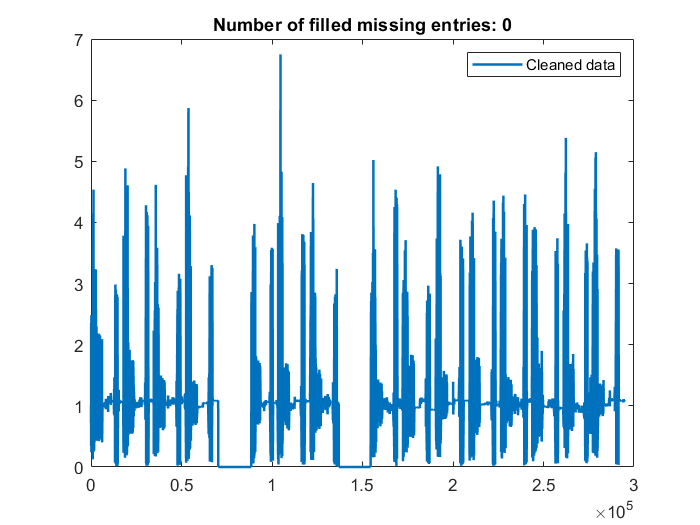


clear all;
% Extract the HAR_UP_Fall_Detection_v3.zip file if required to get the *.csv 
%
input = readtable('HAR_UP_Fall_Detection_v3.csv');
%net = load("LSTM_FallDetection_Net.mat");
%net2 = net.net2;
cell_r = 1;

% Subject 8 has incomplete data, therefore discarded for this experiment

for Subject = [1,2,3,4,6,7,10,11,12,13,14,15,16,17]
    for Activity = 1:11
        for Trial = 1:3
            CompCode = 1000 * Subject + 10 * Activity + Trial;
            OutTable = input(ismember(input.CompareCode,CompCode),:); 
            sqrt_AnkleAccelerometer         {cell_r,1} =    table2array(OutTable (:,1))';
            sqrt_AnkleAngularVelocity       {cell_r,1} =    table2array(OutTable (:,2))';
            sqrt_RightPocketAccelerometer   {cell_r,1} =    table2array(OutTable (:,3))';
            sqrt_RightPocketAngularVelocity {cell_r,1} =    table2array(OutTable (:,4))';	

            sqrt_BeltAccelerometer          {cell_r,1} =    table2array(OutTable (:,5))';
            sqrt_BeltAngularVelocity	    {cell_r,1} =    table2array(OutTable (:,6))';
            sqrt_NeckAccelerometer	    {cell_r,1} =    table2array(OutTable (:,7))';
            sqrt_NeckAngularVelocity	    {cell_r,1} =    table2array(OutTable (:,8))';
            sqrt_WristAccelerometer	    {cell_r,1} =    table2array(OutTable (:,9))';
            sqrt_WristAngularVelocity       {cell_r,1} =    table2array(OutTable (:,10))';

            cell_r = cell_r + 1 ;
        end
    end
end

% Subject 8 has incomplete data, therefore discarded for this experiment
% 
% for Subject = 9:17
%     for Activity = 1:11
%         for Trial = 1:3
%             CompCode = 1000 * Subject + 10 * Activity + Trial;
%             OutTable = input(ismember(input.CompareCode,CompCode),:); 
%             sqrt_AnkleAccelerometer{cell_r,1}    =    table2array(OutTable (:,1))';
%             sqrt_AnkleAngularVelocity{cell_r,1}  =    table2array(OutTable (:,2))';
% %             sqrt_RightPocketAccelerometer{cell_r,1}	 =    table2array(OutTable (:,3))';
% %             sqrt_RightPocketAngularVelocity{cell_r,1} =    table2array(OutTable (:,4))';	
%             sqrt_BeltAccelerometer{cell_r,1}	   =      table2array(OutTable (:,5))';
%             sqrt_BeltAngularVelocity	{cell_r,1} =    table2array(OutTable (:,6))';
%             sqrt_NeckAccelerometer	{cell_r,1} =    table2array(OutTable (:,7))';
%             sqrt_NeckAngularVelocity	{cell_r,1} =    table2array(OutTable (:,8))';
%             sqrt_WristAccelerometer	{cell_r,1} =    table2array(OutTable (:,9))';
%             sqrt_WristAngularVelocity   {cell_r,1} =    table2array(OutTable (:,10))';
% 
%             cell_r = cell_r + 1 ;
%         end
%     end
% end


fileID = fopen('Fall_Detection_Target4.txt');
target1 = textscan(fileID,'%s');
fclose(fileID);

target = categorical(target1{1,1});
YTest = target;


## FFT then LSTM on Signal : Setup LSTM Architecture

The sequenceInputLayer size is two due to we have two features of the original signal to input inside the new LSTM

maxEpochs = 30 ;
miniBatchSize = 32  ;
sequenceLength = 1000;
initialLearnRate = 0.01;
% For binary LSTM, number of classes is 2
numClasses = 2;

layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'InitialLearnRate', initialLearnRate, ...
    'GradientThreshold', 1, ...
    'plots','training-progress', ...
    'Verbose',false);

## Feature Extraction, Training and Testing

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


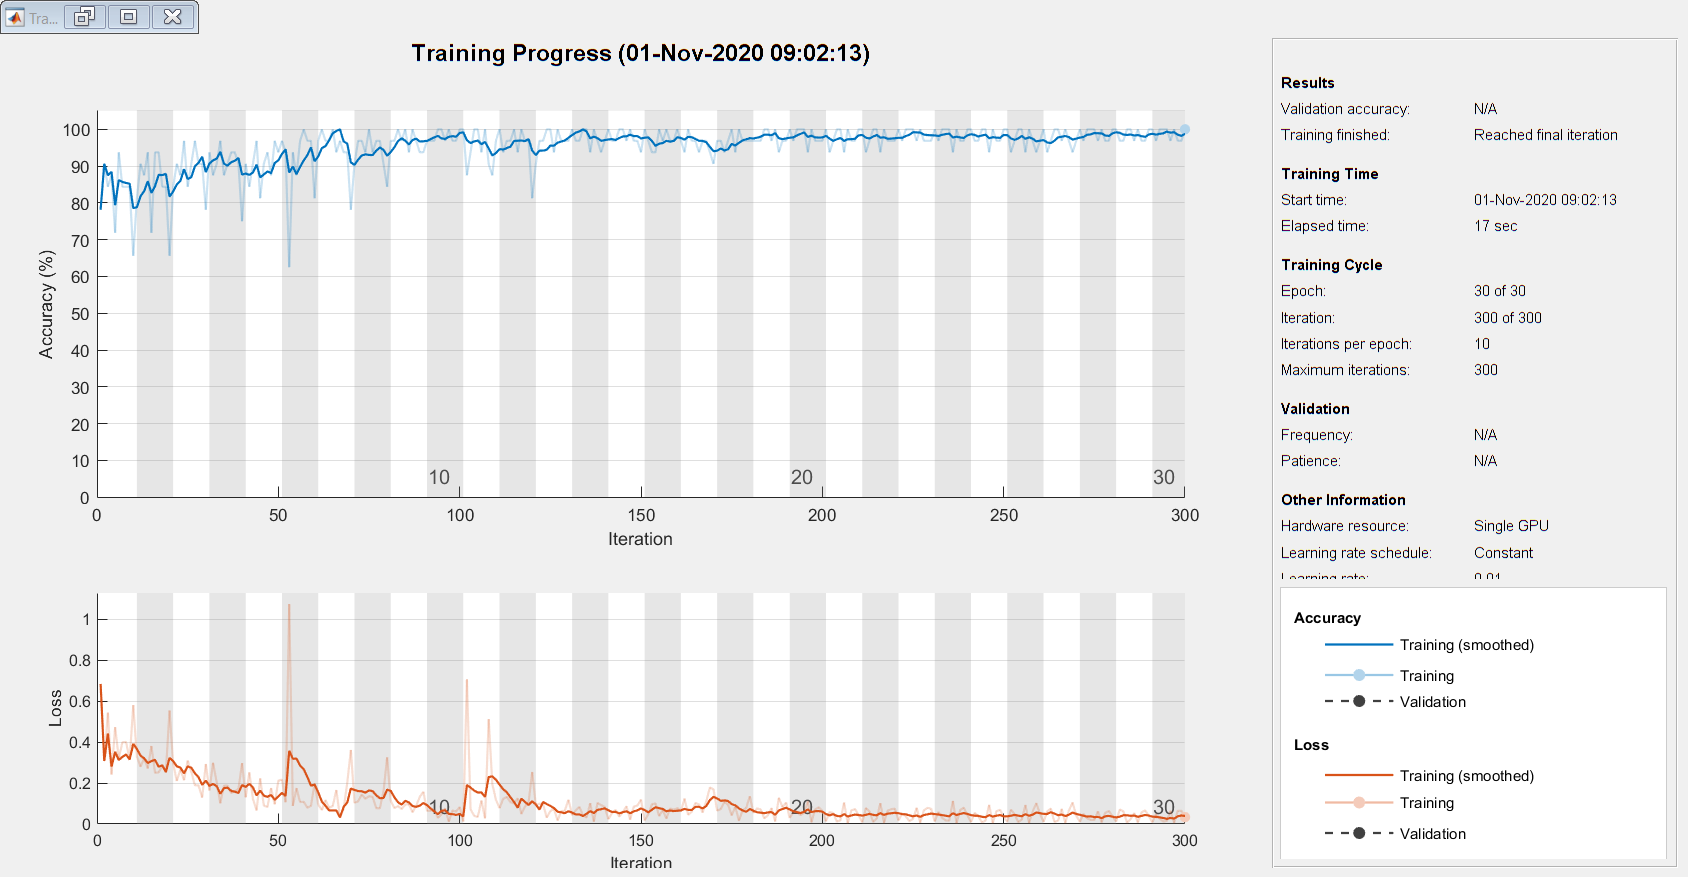

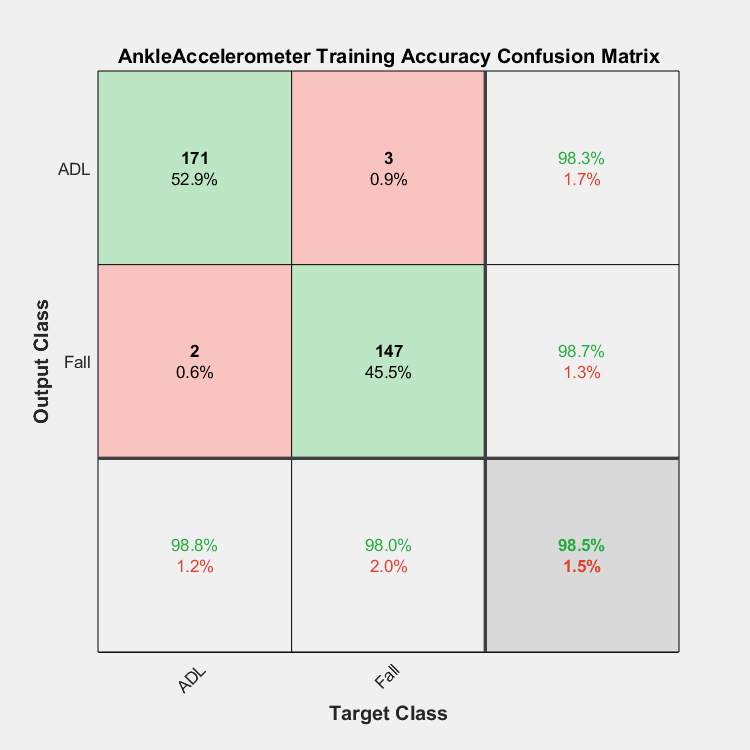

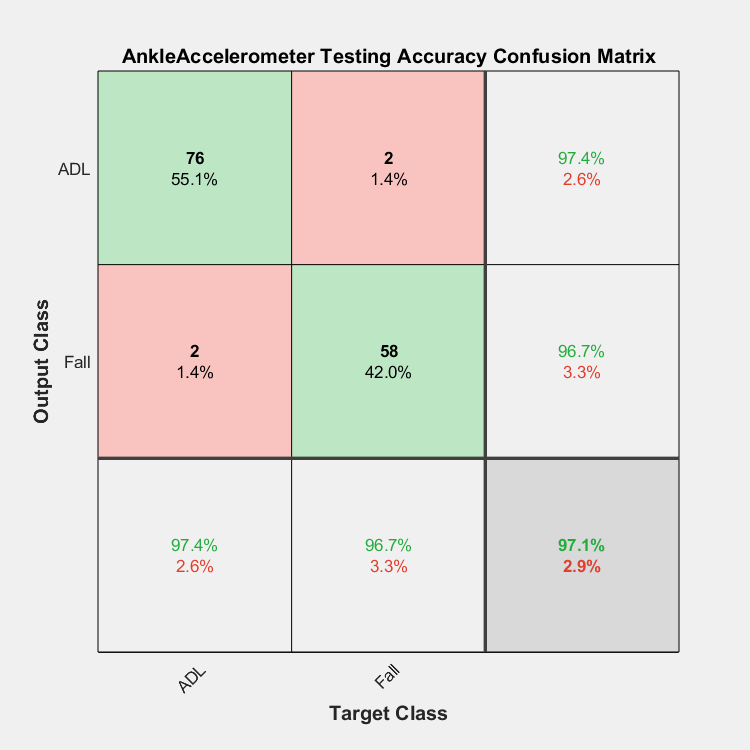

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


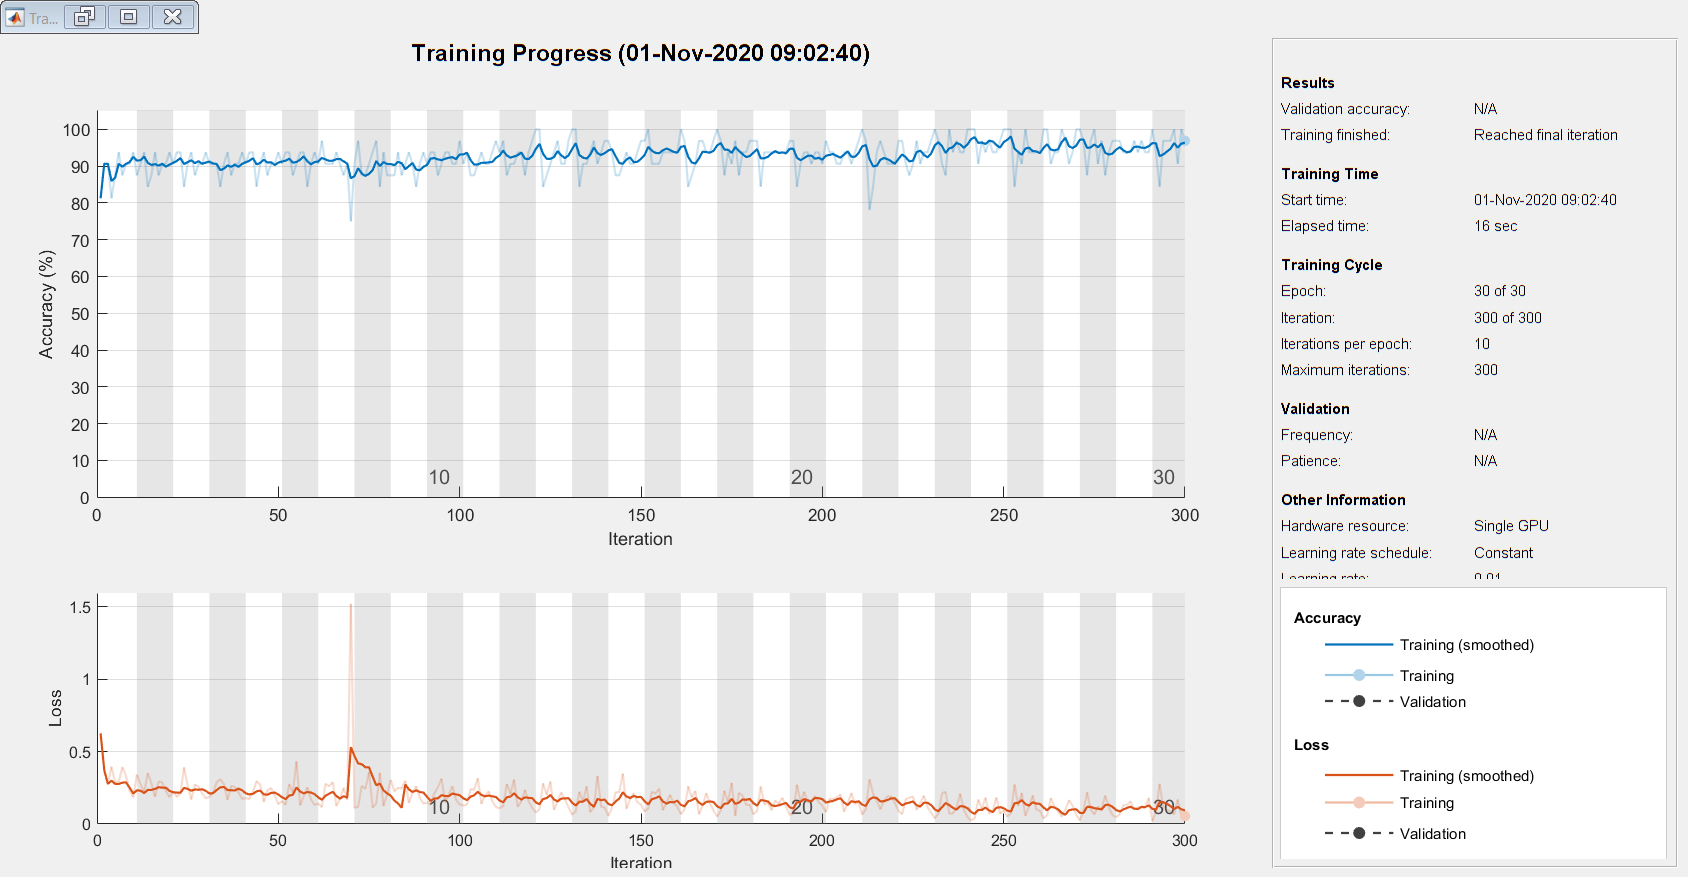

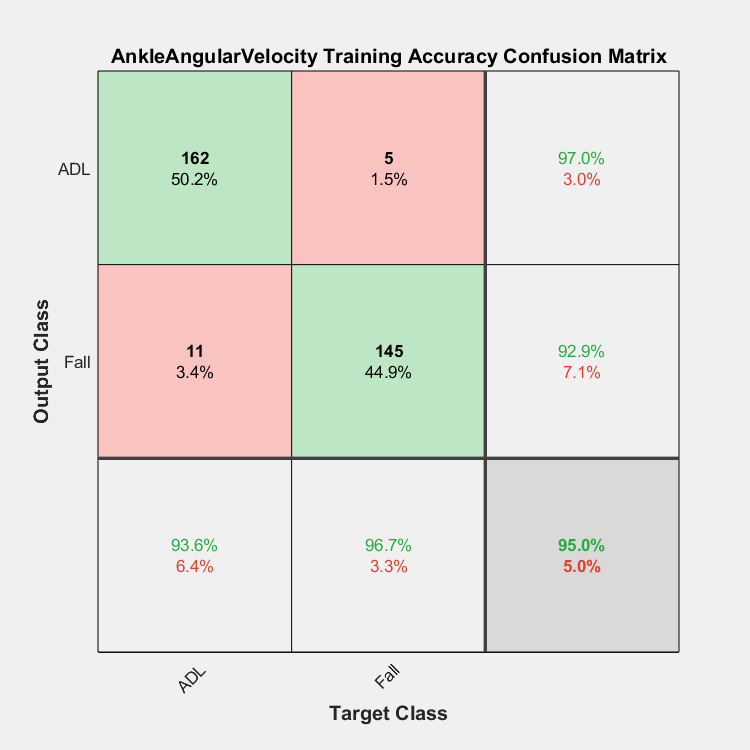

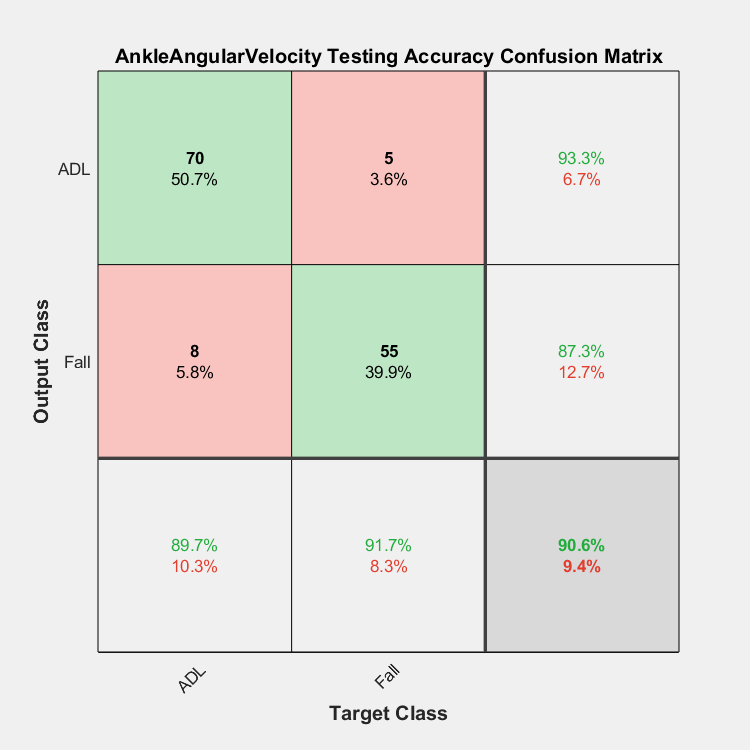

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


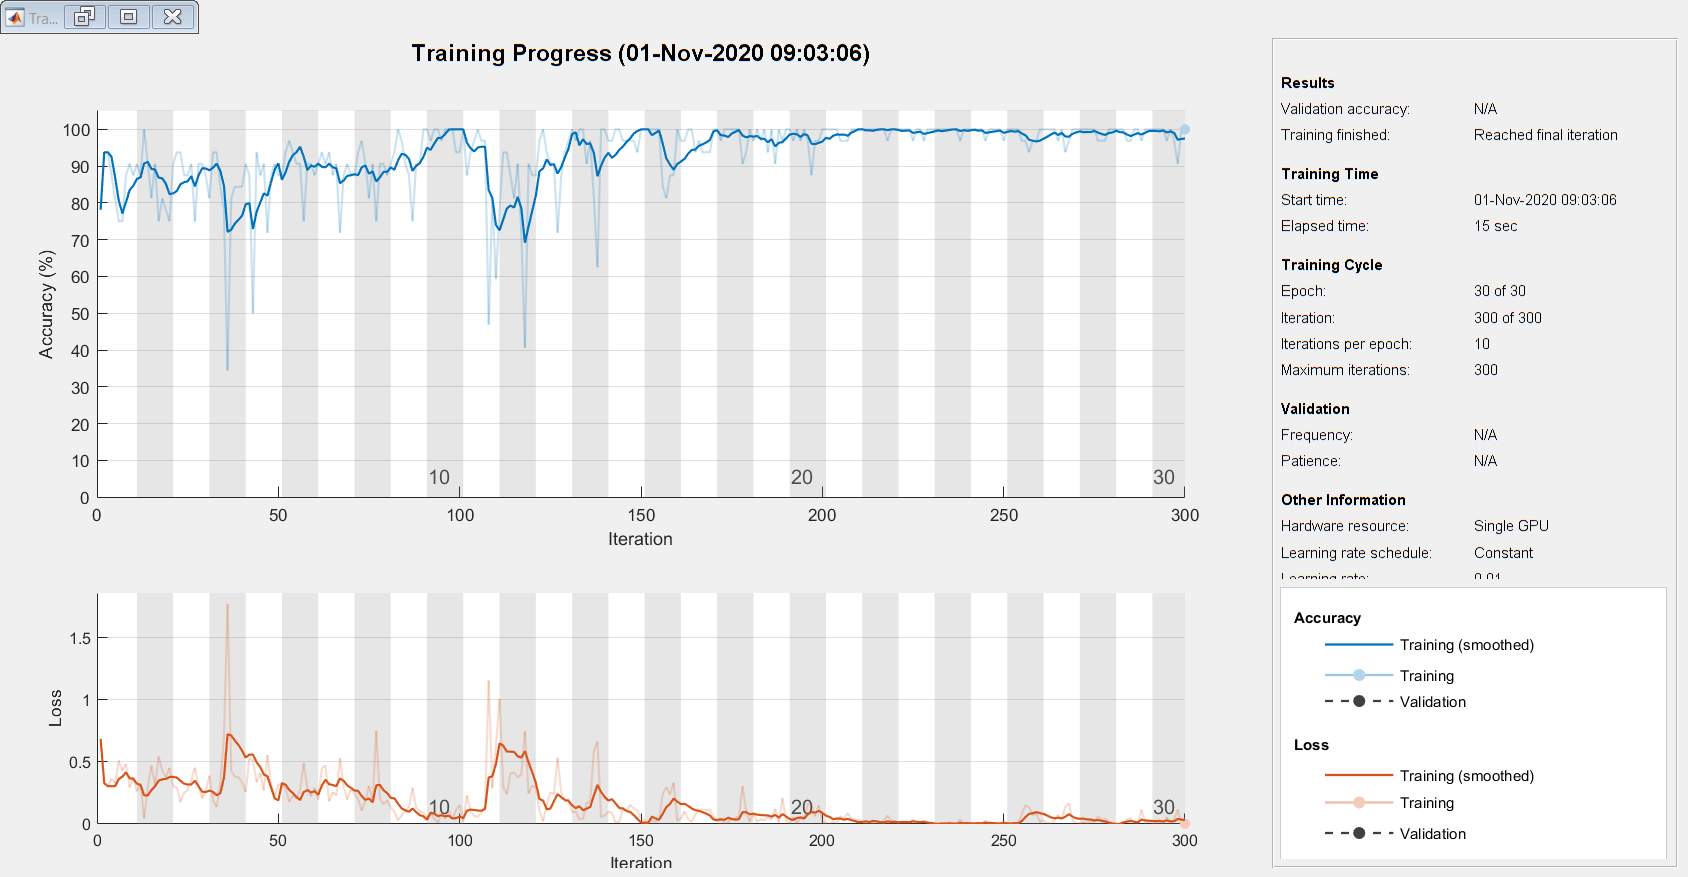

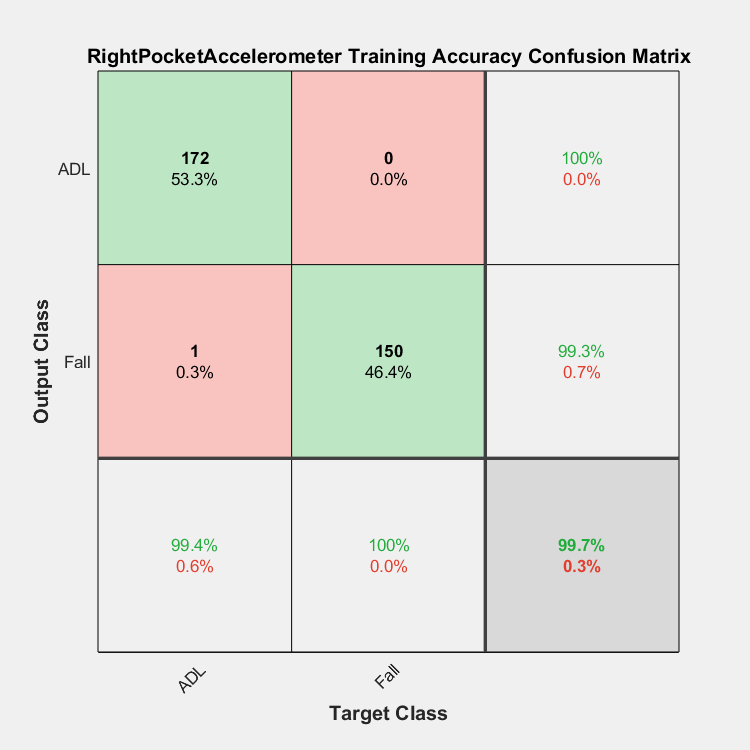

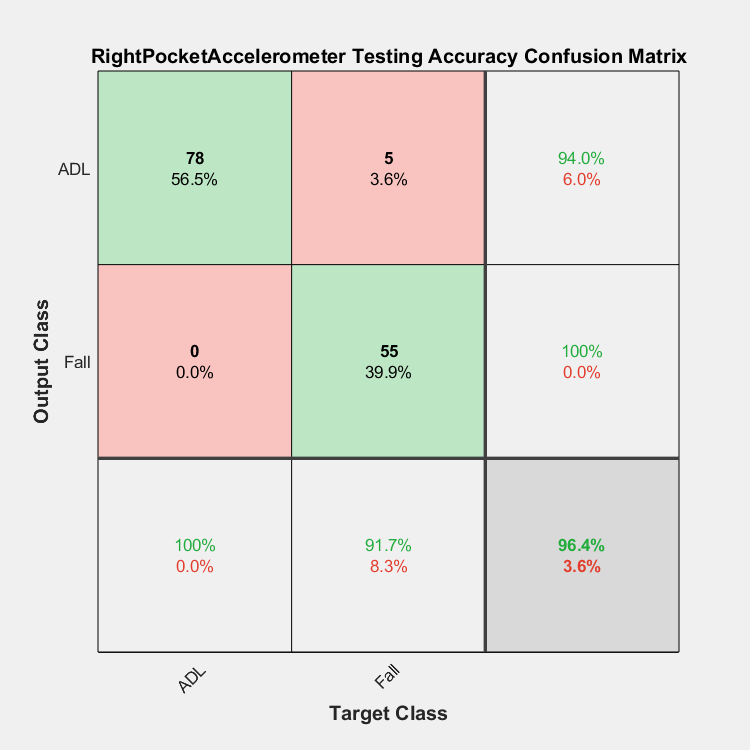

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


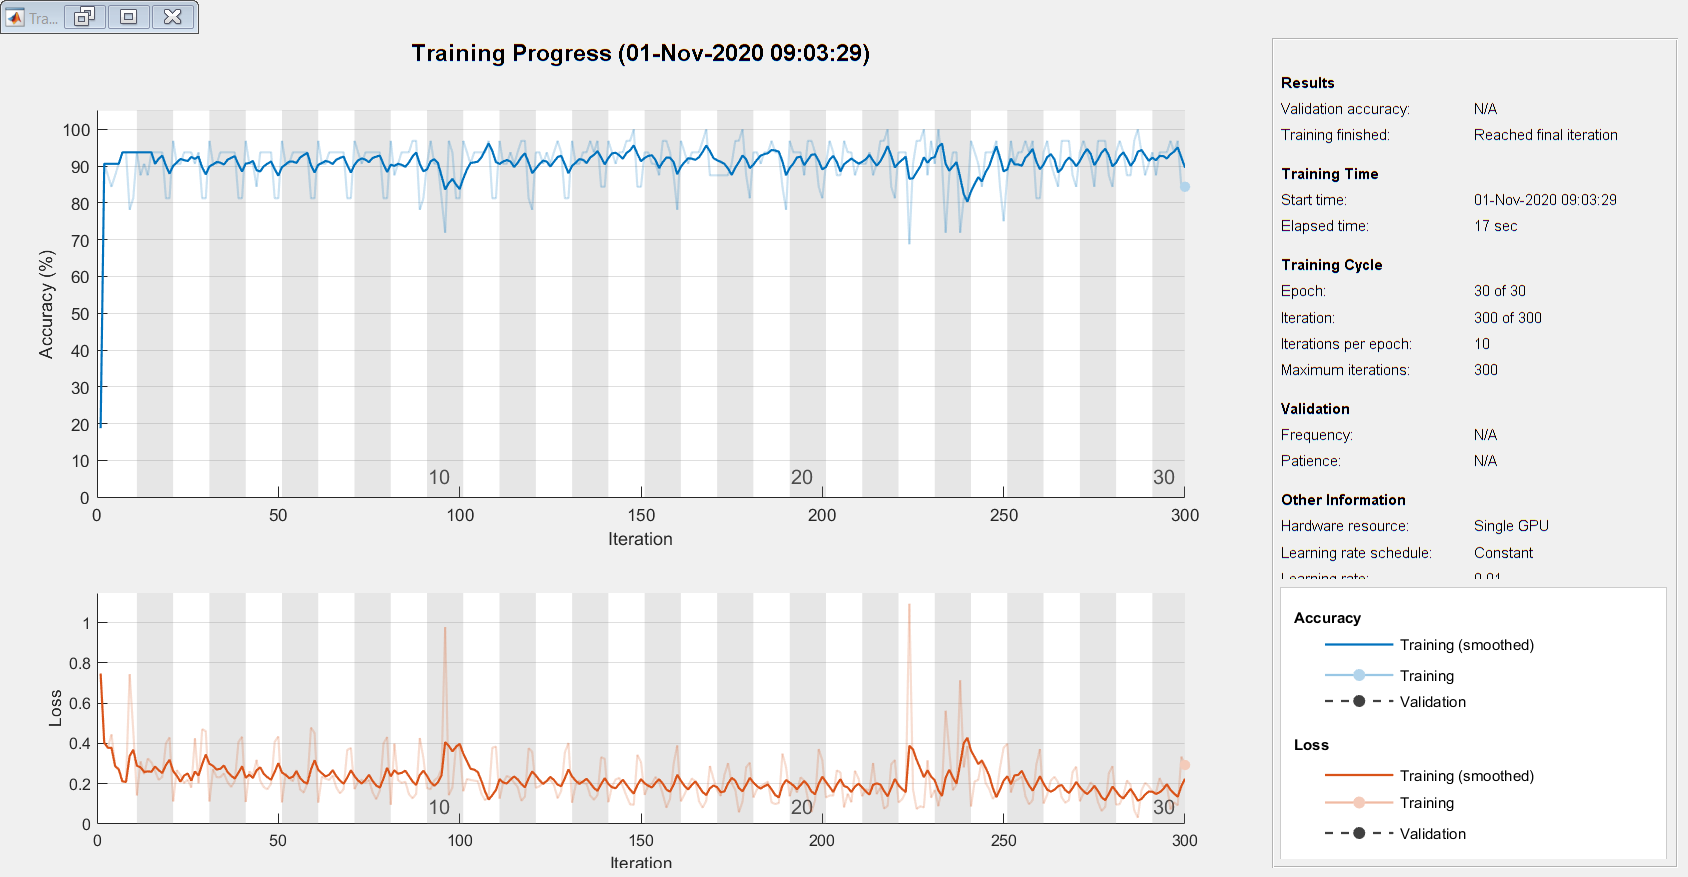

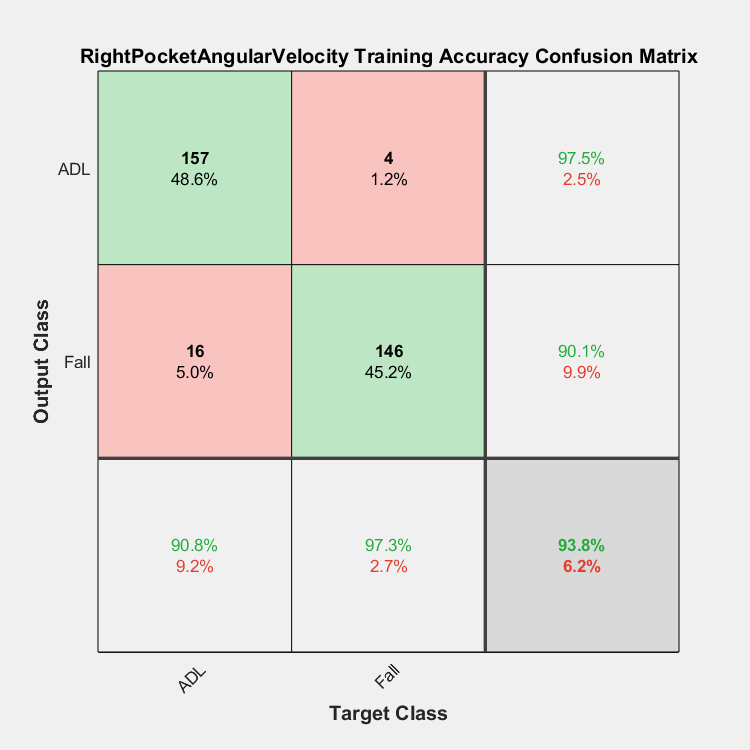

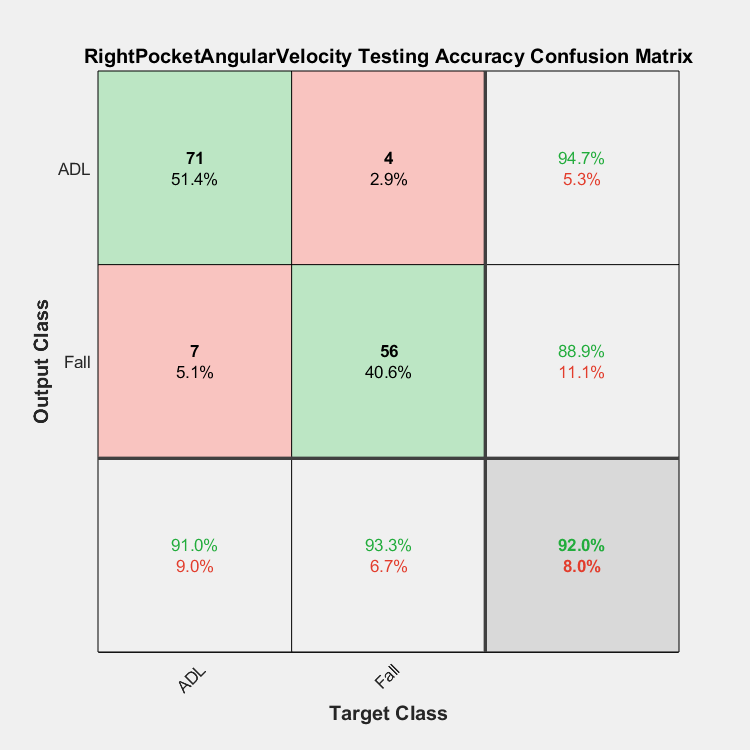

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


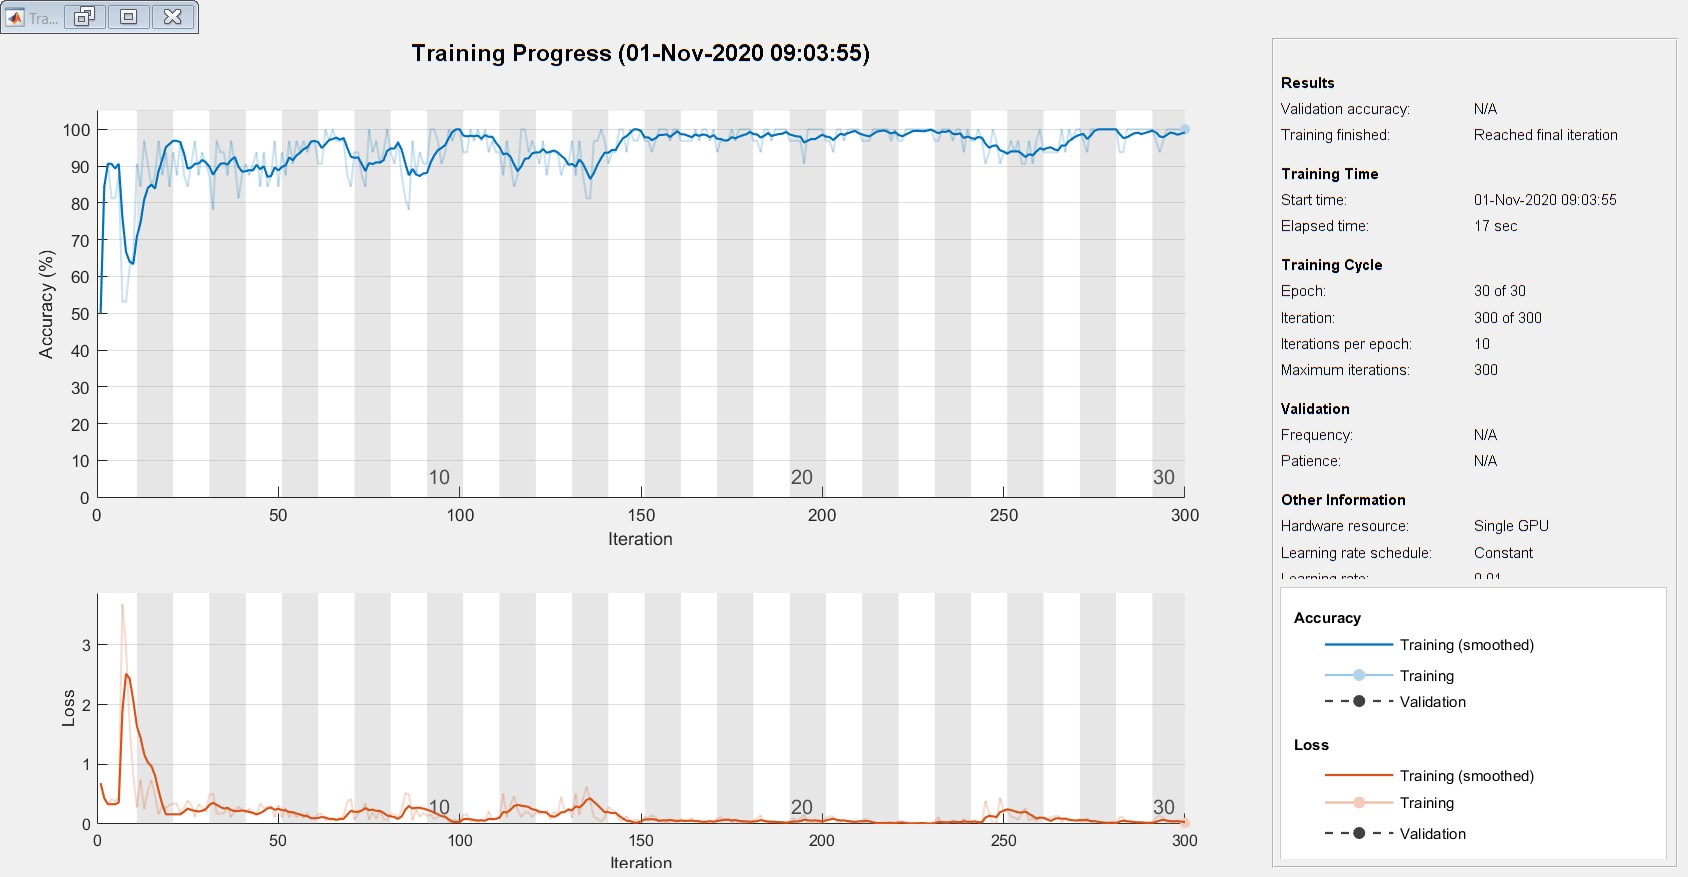

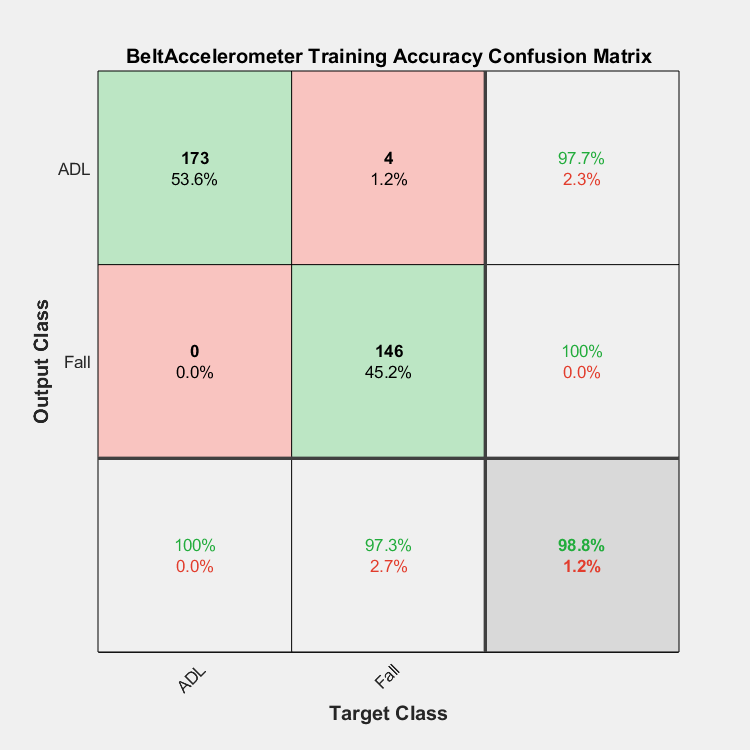

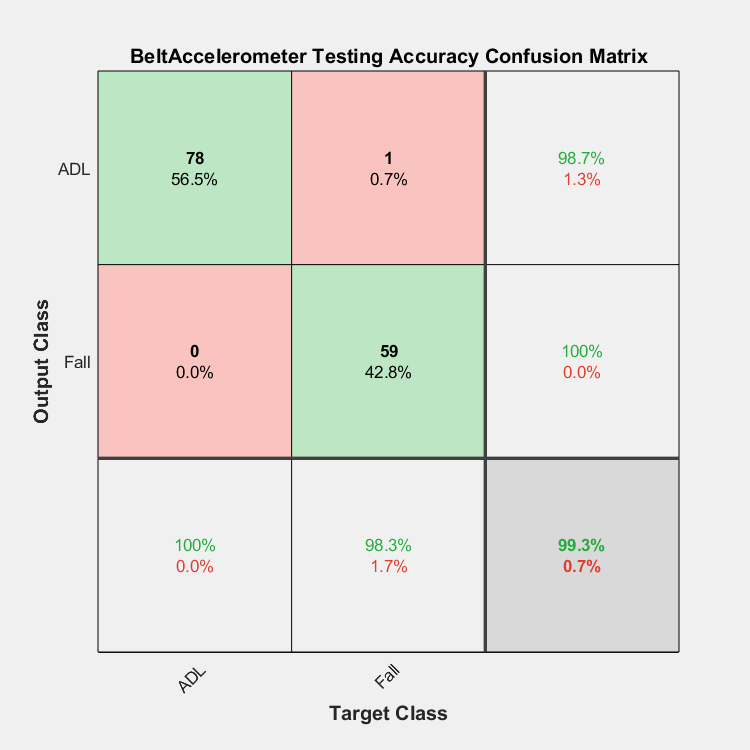

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


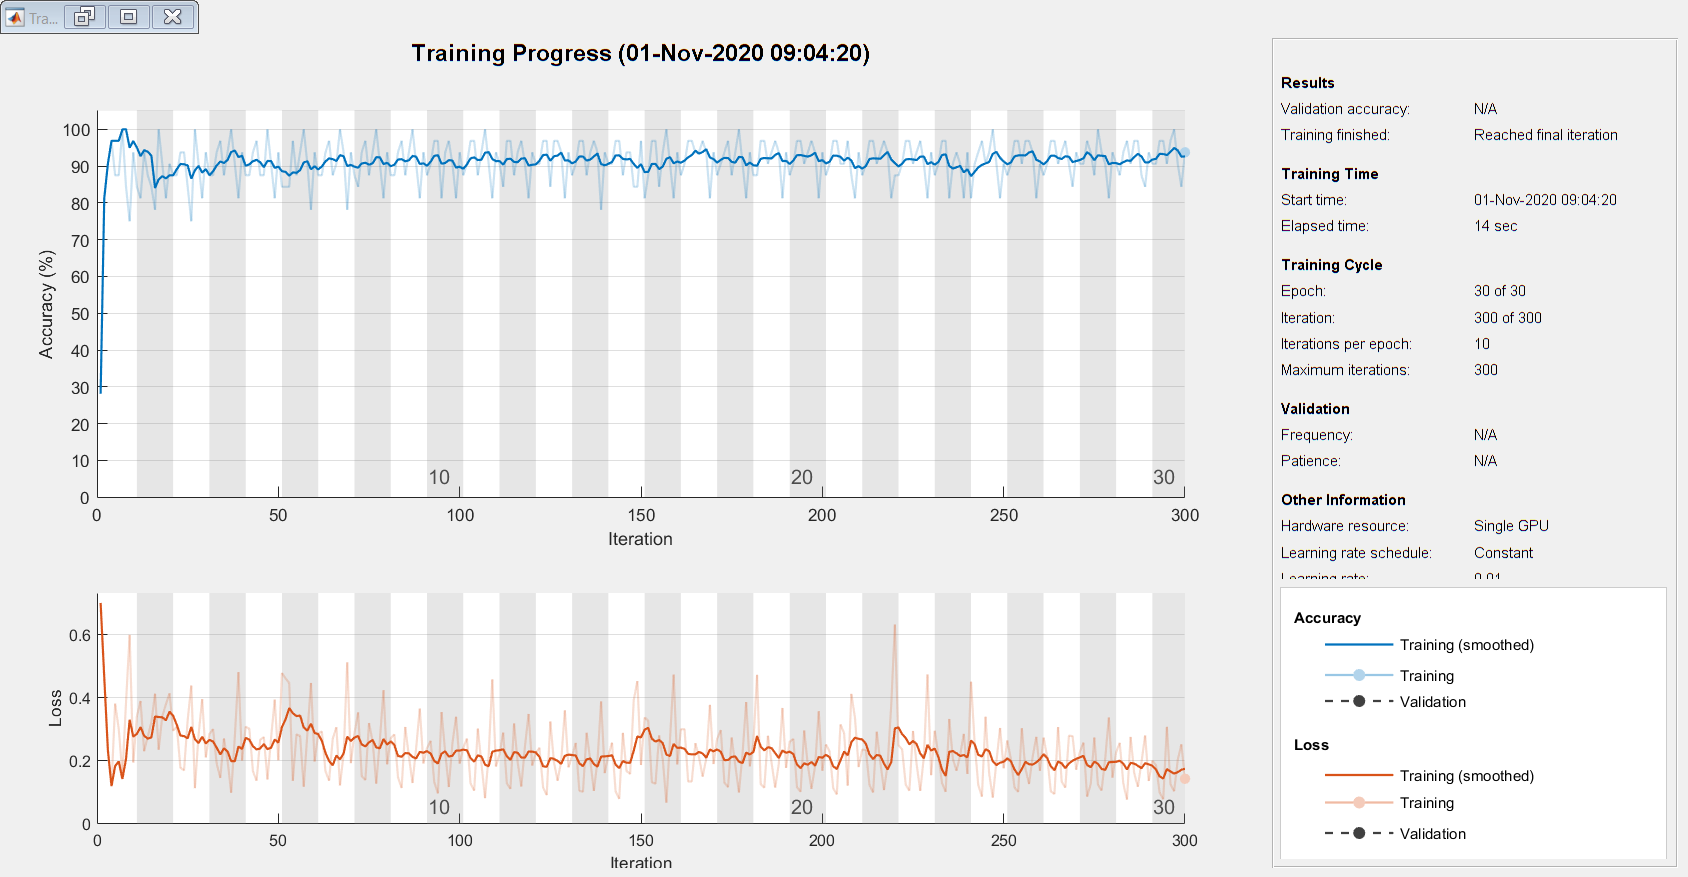

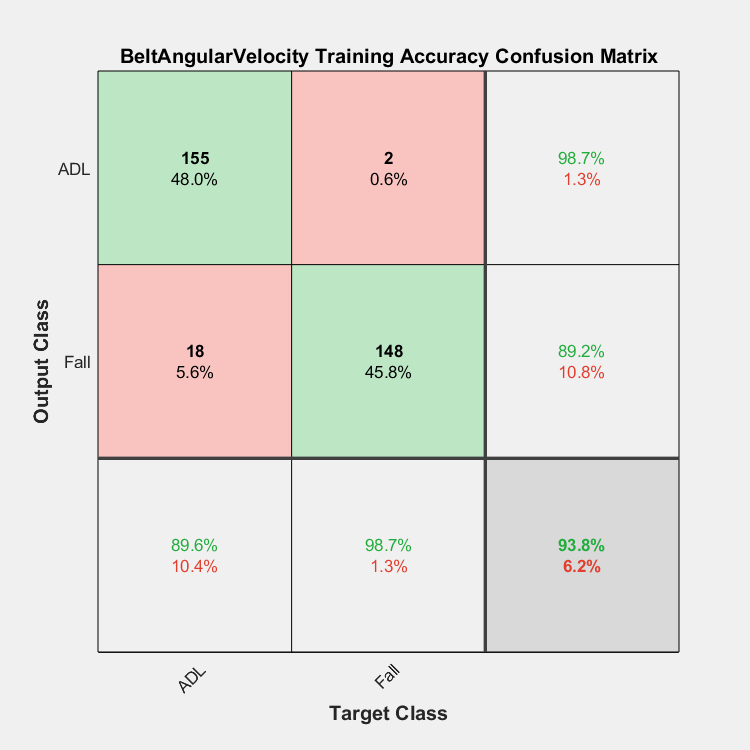

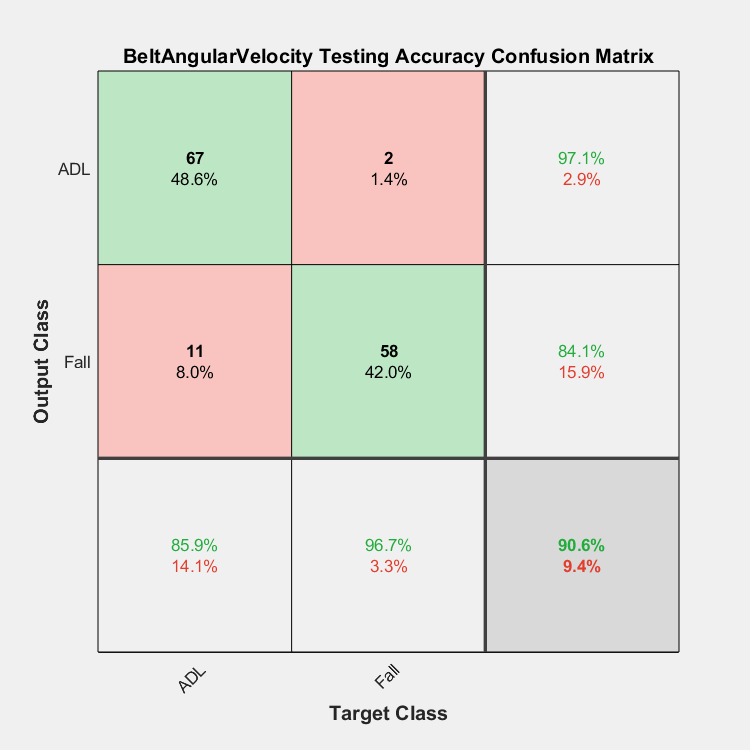

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


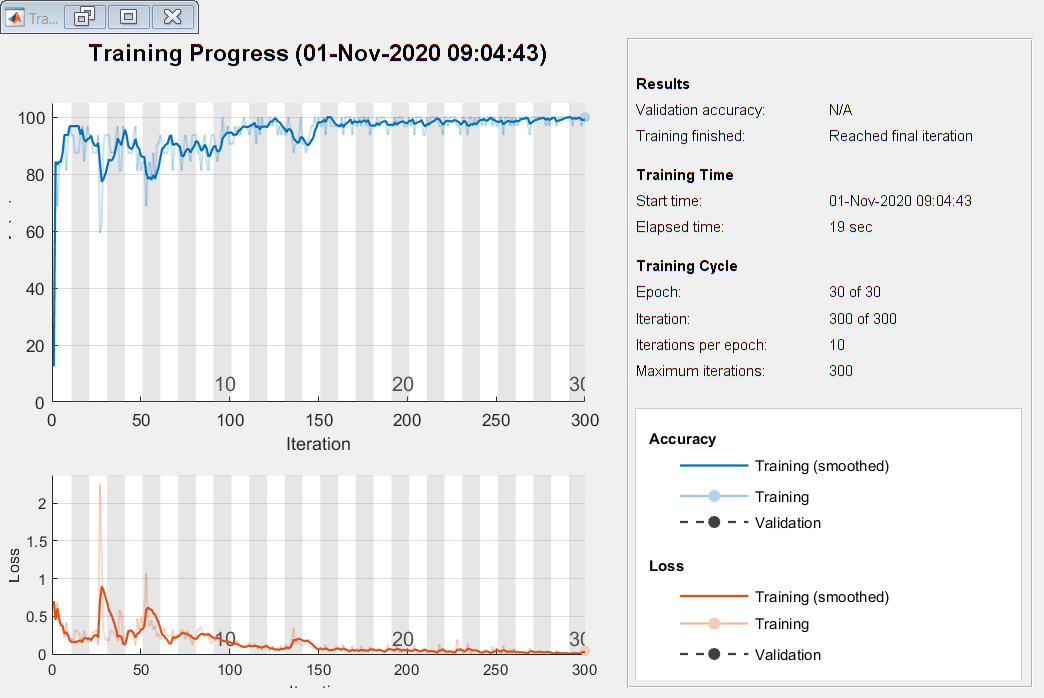

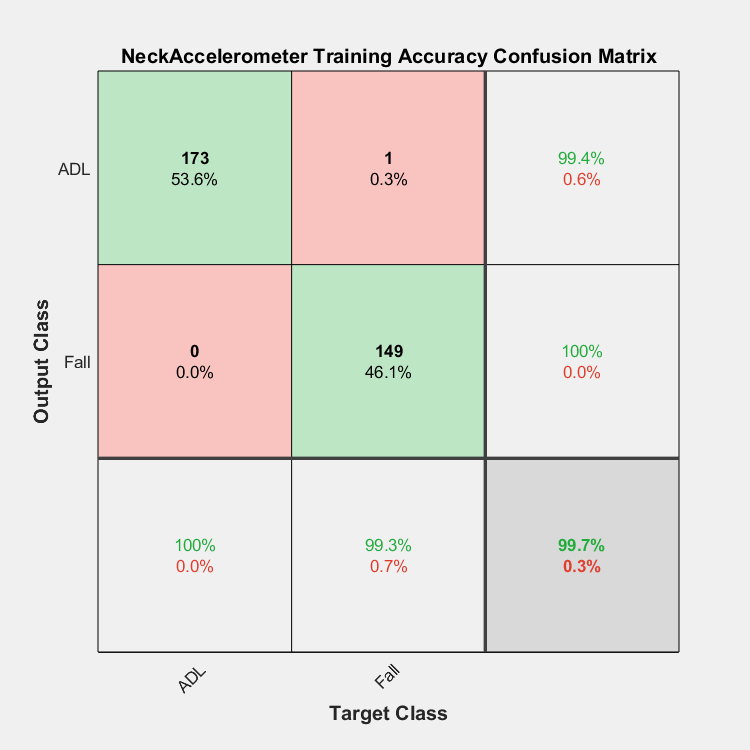

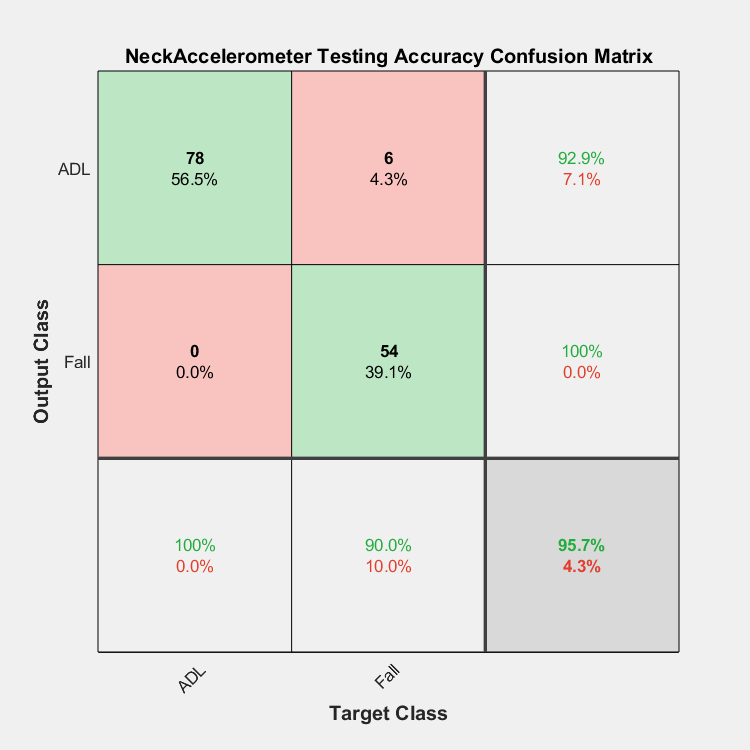

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


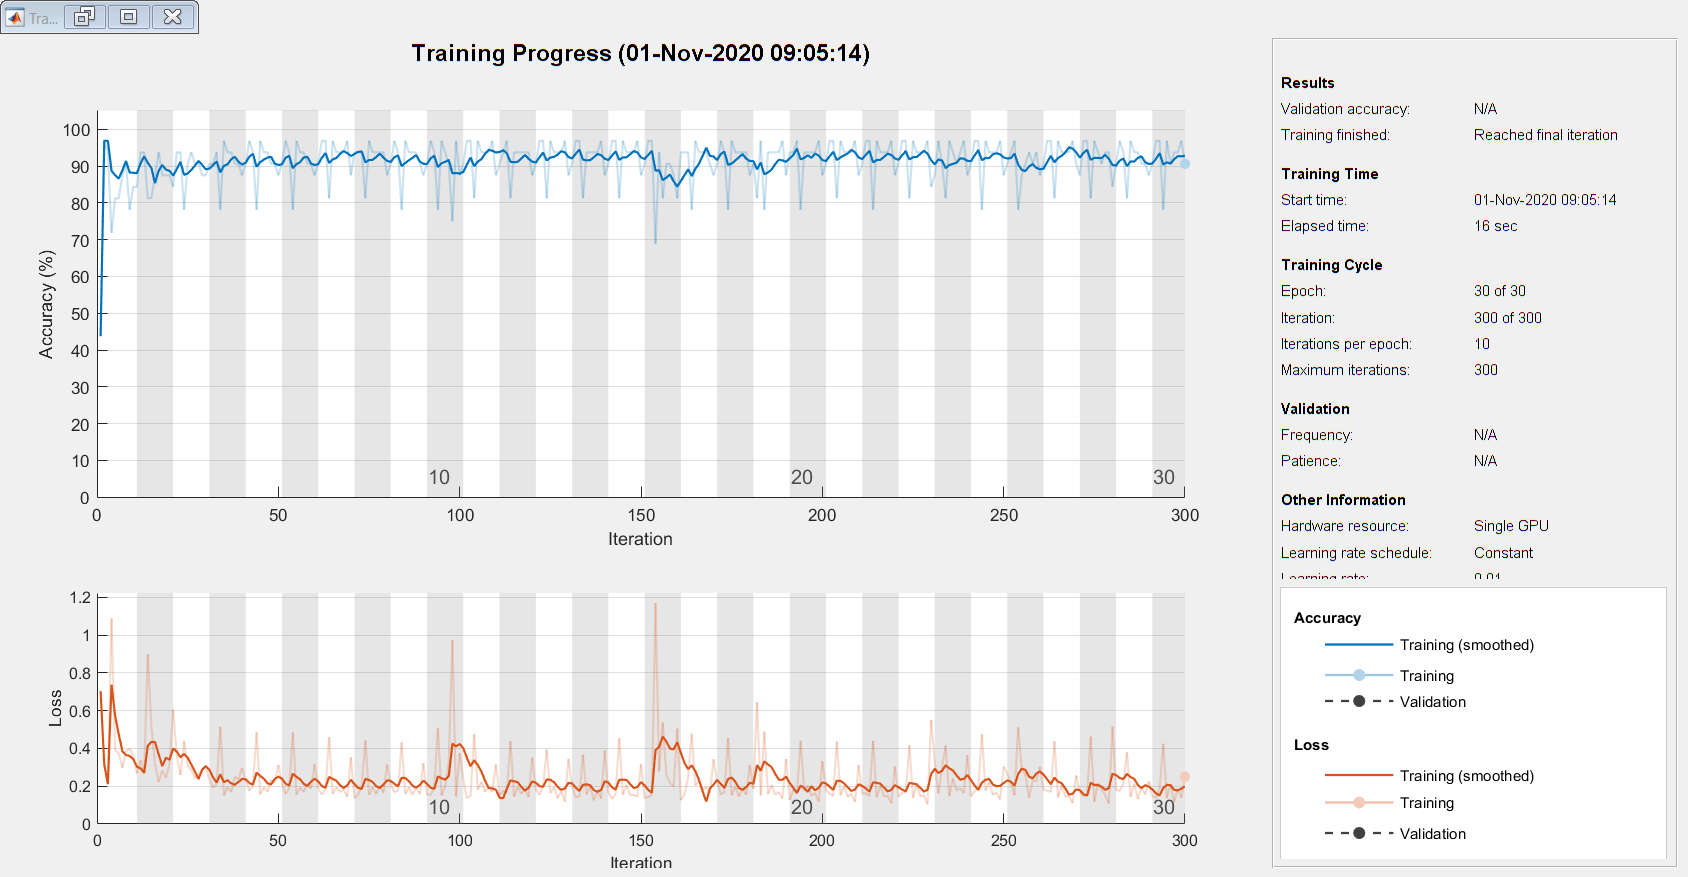

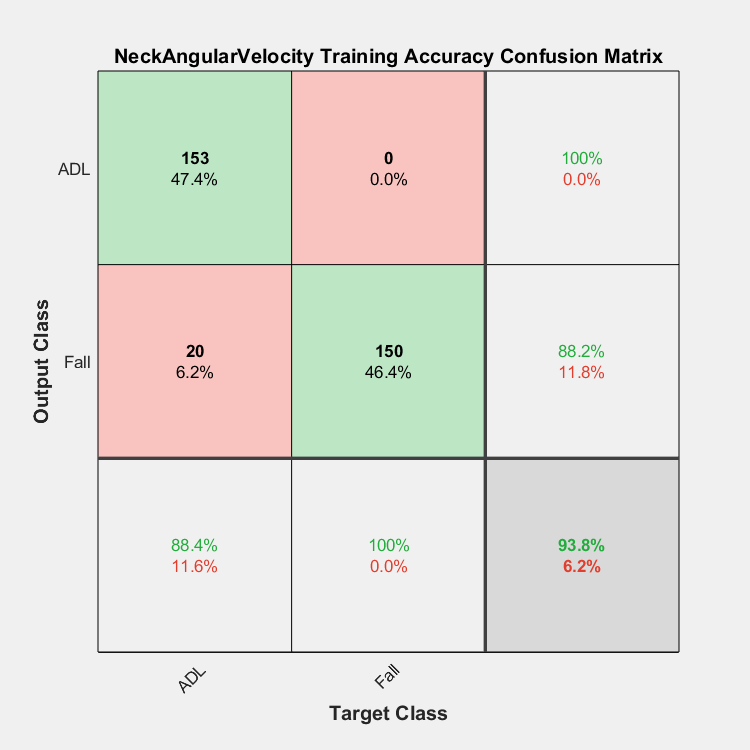

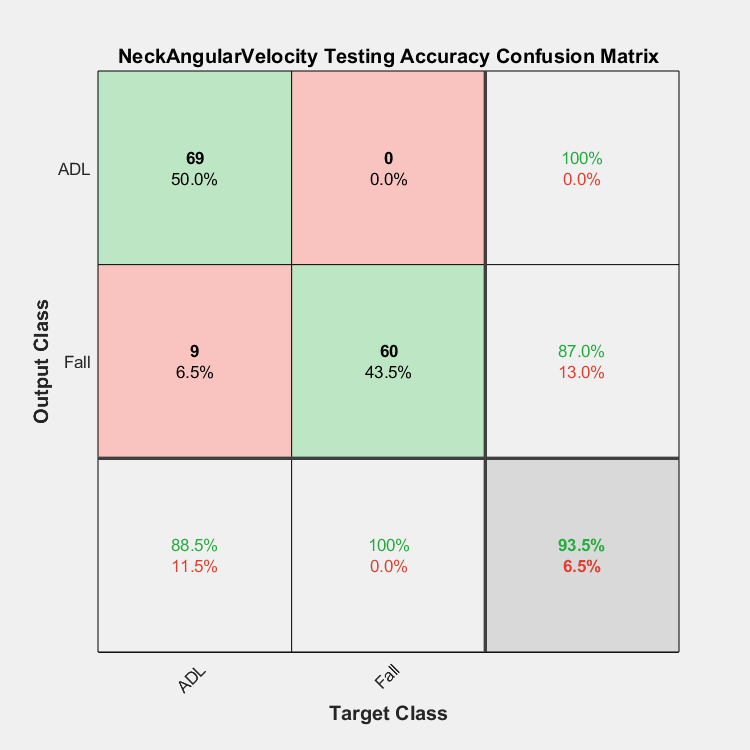

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


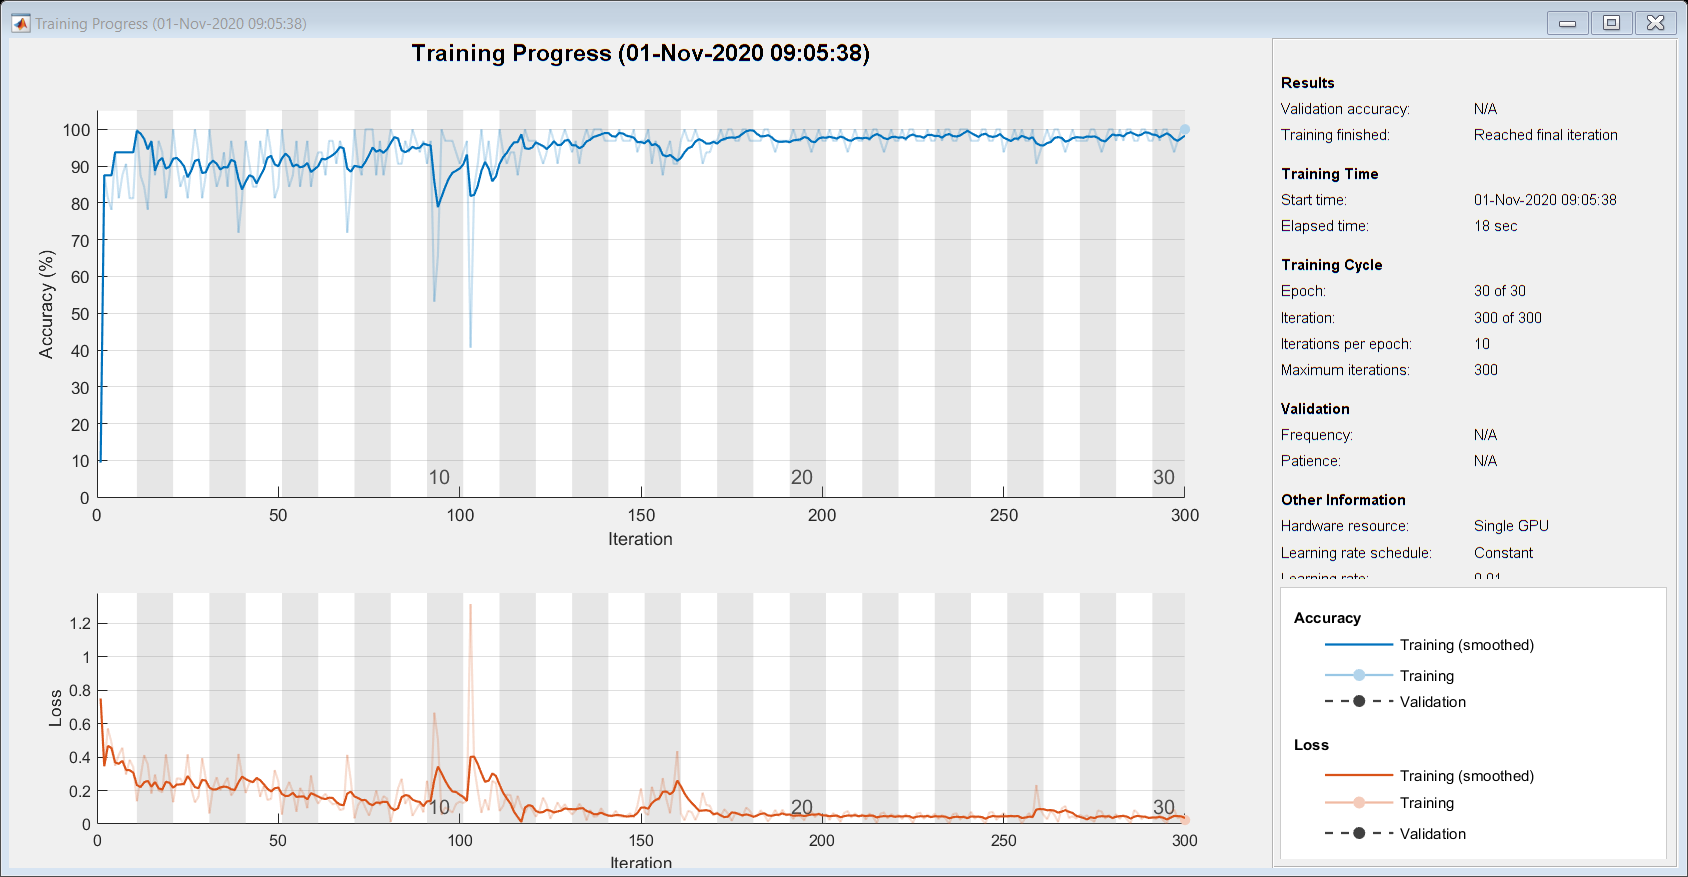

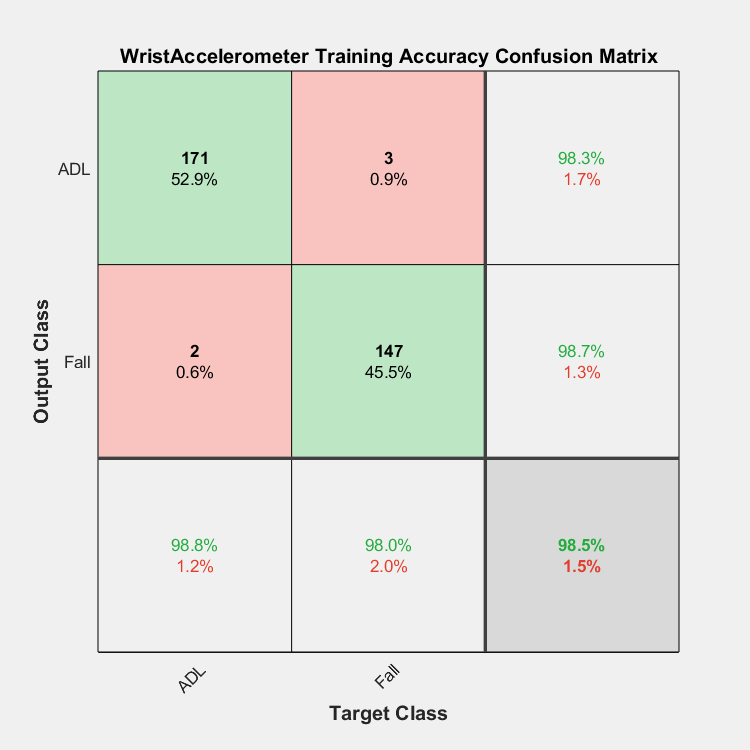

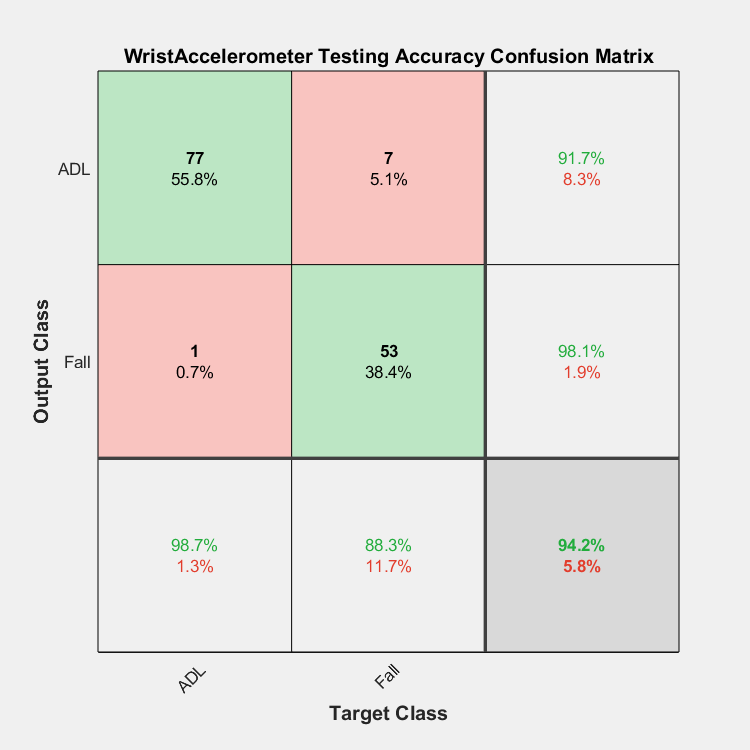

cf_name = 1×10 cell array
    {'AnkleAccelerometer'}    {'AnkleAngularVelocity'}    {'RightPocketAccelerometer'}    {'RightPocketAngularVelocity'}    {'BeltAccelerometer'}    {'BeltAngularVelocity'}    {'NeckAccelerometer'}    {'NeckAngularVelocity'}    {'WristAccelerometer'}    {'WristAngularVelocity'}


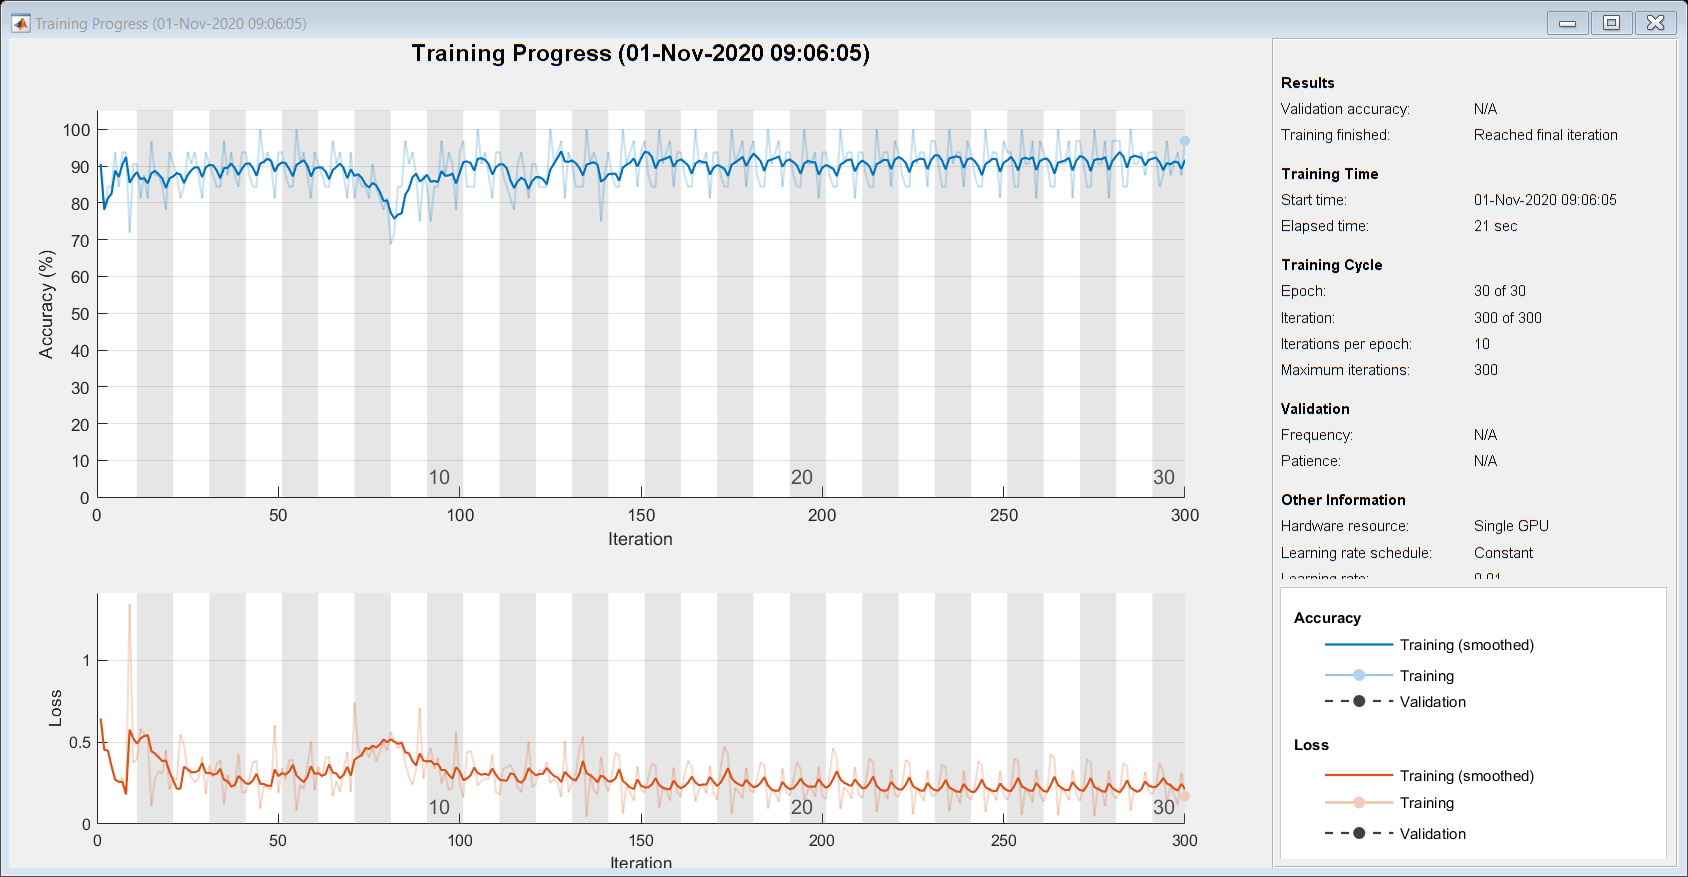

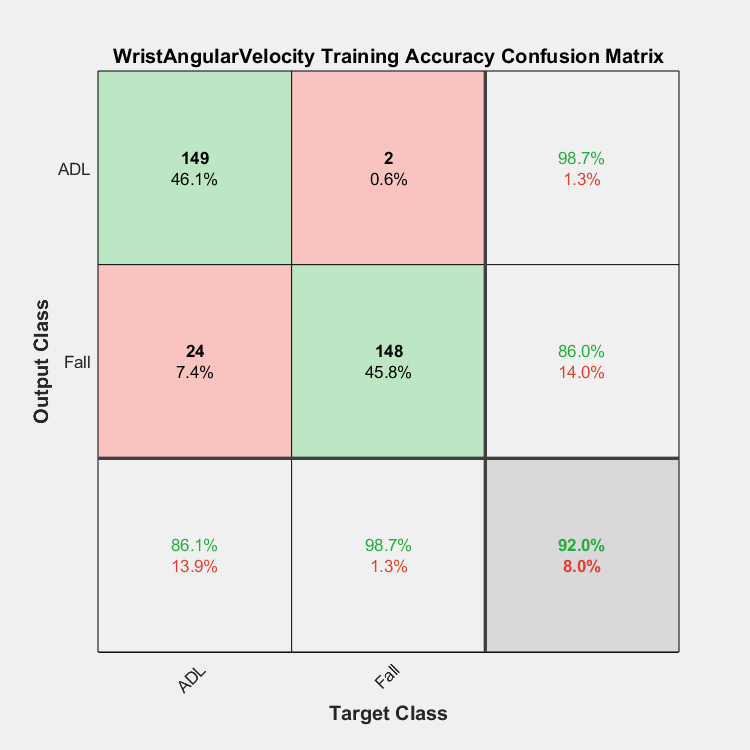

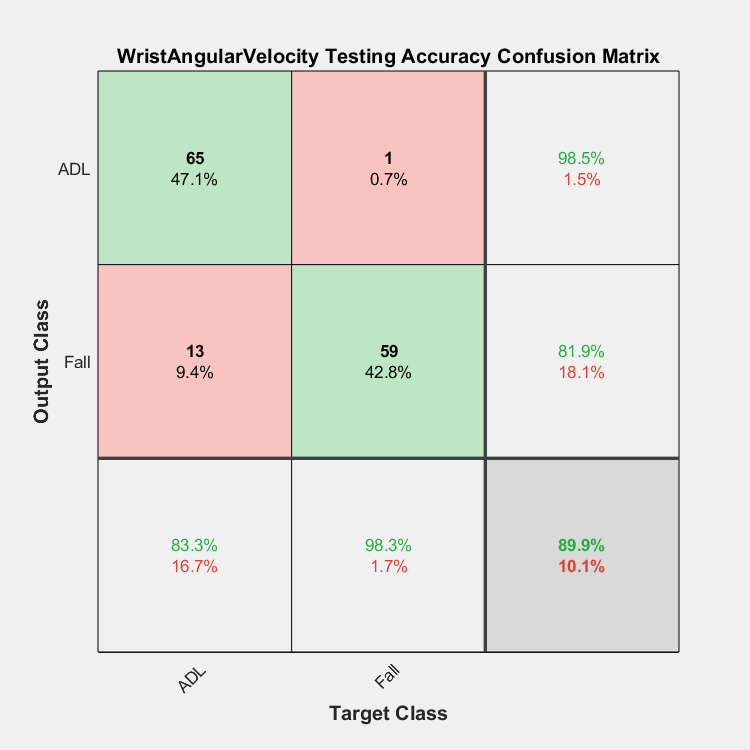



fs = 100;
counter = 1;

% Ommiting sqrt_RightPocketAccelerometer,sqrt_RightPocketAngularVelocity as
% they have missing values
%
for XTest1 = {sqrt_AnkleAccelerometer,sqrt_AnkleAngularVelocity,sqrt_RightPocketAccelerometer,sqrt_RightPocketAngularVelocity,...
        sqrt_BeltAccelerometer,sqrt_BeltAngularVelocity,sqrt_NeckAccelerometer,sqrt_NeckAngularVelocity,...
        sqrt_WristAccelerometer,sqrt_WristAngularVelocity}, cf_name = {'AnkleAccelerometer','AnkleAngularVelocity','RightPocketAccelerometer',...
        'RightPocketAngularVelocity','BeltAccelerometer','BeltAngularVelocity', ...
        'NeckAccelerometer','NeckAngularVelocity','WristAccelerometer','WristAngularVelocity'}
    
% for XTest1 = {sqrt_AnkleAccelerometer,sqrt_AnkleAngularVelocity,...
%     sqrt_BeltAccelerometer,sqrt_BeltAngularVelocity,sqrt_NeckAccelerometer,sqrt_NeckAngularVelocity,...
%     sqrt_WristAccelerometer,sqrt_WristAngularVelocity}, cf_name = {'AnkleAccelerometer','AnkleAngularVelocity',...
%     'BeltAccelerometer','BeltAngularVelocity', ...
%     'NeckAccelerometer','NeckAngularVelocity','WristAccelerometer','WristAngularVelocity'}
    
    data = [XTest1{1,1},target1{1,1}];
    % Data partition (NON RANDOM) (train: 70%, test: 30%)
    idxL(1:size(data,1)*70/100) = 0;
    idxL(1+size(data,1)*70/100:size(data,1)) = 1;
    idx = logical(idxL);
    % Separate to training and test data
    dataTrainCombo = data(~idx,:);
    dataTrainTarget = dataTrainCombo(:,2);
    dataTrain = dataTrainCombo(:,1);
    dataTestCombo  = data(idx,:);  
    dataTest =  dataTestCombo(:,1);
    dataTestTarget = dataTestCombo(:,2);
        
    instfreqTrain1 = cellfun(@(x)instfreq(x,fs)',dataTrain,'UniformOutput',false);
    pentropyTrain1 = cellfun(@(x)pentropy(x,fs)',dataTrain,'UniformOutput',false);
    XTrain1_2 = cellfun(@(x,y)[x;y],instfreqTrain1,pentropyTrain1,'UniformOutput',false);
    
    XV1 = [XTrain1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTrainSD = cellfun(@(x)(x-mu1)./sg1,XTrain1_2,'UniformOutput',false);
    
    net2 = trainNetwork(XTrainSD,categorical(dataTrainTarget),layers,options);
    % Store the LSTM nets inside the netLSTM cell
    netLSTM {counter,1} = net2;
    
    txtTrain = string( cf_name{1,counter}) + ' Training Accuracy';
    txtTest = string( cf_name{1,counter}) + ' Testing Accuracy';
    
    trainPred = classify(net2,XTrainSD);
    catTrain = categorical(dataTrainTarget);
    trainPredCombo {counter} = [catTrain(:,1),trainPred(:,1)];
    figure;
    plotconfusion(categorical(dataTrainTarget'),trainPred',txtTrain);
    
    instfreqTest1 = cellfun(@(x)instfreq(x,fs)',dataTest,'UniformOutput',false);
    pentropyTest1 = cellfun(@(x)pentropy(x,fs)',dataTest,'UniformOutput',false);
    XTest1_2 = cellfun(@(x,y)[x;y],instfreqTest1,pentropyTest1,'UniformOutput',false);
    
    XV1 = [XTest1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTestSD1_2 = cellfun(@(x)(x-mu1)./sg1,XTest1_2,'UniformOutput',false);
        
    testPred1 = classify(net2,XTestSD1_2);
    catTest = categorical(dataTestTarget);
    testPredCombo {counter} = [catTest(:,1),testPred1(:,1)];
    figure;
    plotconfusion(categorical(dataTestTarget'), testPred1', txtTest );
    
    counter = counter +1;
end    